# Transformación de brillo

## Transformación $\gamma$

La **transformación gamma** es una operación de corrección no lineal que modifica la intensidad de los píxeles mediante una potencia. Matemáticamente se expresa como $s=c \cdot p^\gamma$, donde $p$ es el valor normalizado del píxel de entrada, $\gamma$ es el exponente y $c$ una constante de escala. Al aplicar esta transformación:

- Si $\gamma<1$, se realzan las regiones oscuras, haciendo visibles detalles en zonas poco iluminadas.

- Si $\gamma>1$, se enfatizan las regiones brillantes, aumentando el contraste en áreas claras.

En imágenes médicas, la corrección gamma permite resaltar estructuras específicas dependiendo del rango de intensidades en el que se encuentren, mejorando así la percepción visual para el análisis clínico.

X = double(imread("/home/erit/Desktop/SIMLab_2025/Imagenes/tac/ct2.14.png"));
X = mean(X,3);
[M,N] = size(X);
X_norm = reshape(normalize(X(:),"range"),M,N);

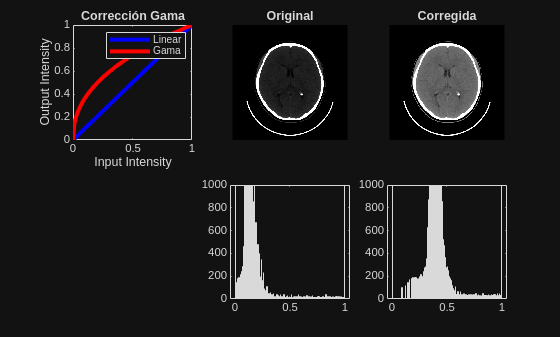


gama = 0.4401;
c = 1;

%noten la operción punto realizda 
p = linspace(0,1,100);

r = c* (p.^gama);
X_gama = c * (X_norm.^gama);

subplot(231)
plot(p,p,'b', "LineWidth",3)
hold on

plot(p, r, 'r', "LineWidth", 3);
xlabel('Input Intensity');
ylabel('Output Intensity');
title('Corrección Gama');
legend('Linear', 'Gama');
hold off;

subplot(232)
imshow(X_norm)
title('Original')

subplot(233)
imshow(X_gama);
title('Corregida');

subplot(235)
histogram(X_norm(:),linspace(0,1,256))
ylim([0 1000])

subplot(236)
histogram(X_gama(:),linspace(0,1,256))
ylim([0 1000])

## Transformación polinomial

Una **transformación polinómica** de píxeles consiste en modificar los valores de intensidad aplicando una función polinomial. Matemáticamente puede expresarse como:


$$s = a_0 + a_1 p + a_2 p^2 + a_3 p^3 + \dots + a_n p^n$$


donde $p$ representa el valor de intensidad original del píxel y $s$ el valor transformado. Al ajustar los coeficientes $a_i$, es posible realzar zonas oscuras, aclarar regiones brillantes o comprimir determinados rangos de intensidad. En el contexto de imágenes médicas, estas transformaciones permiten resaltar estructuras específicas que no se distinguen adecuadamente con transformaciones lineales simples.

Hay que recordar que el rango de la función y el dominio es de $[0,1]$. Es por ello que los coeficientes del polinomio se deben ajustar para poder cumplir con esta restricción. La intención de usar un polinomio es generar una función suave que se ajuste a una forma deseable.

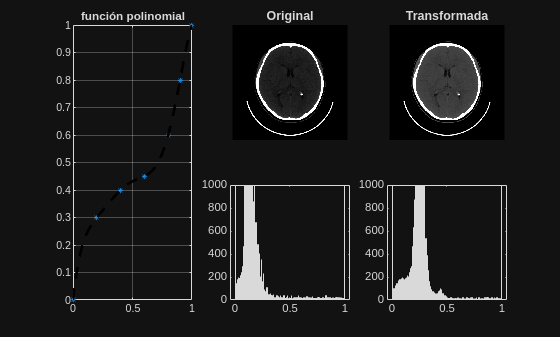

x_o = [0, 0.2, 0.4, 0.6, 0.8, 0.9, 1];
y_o = [0, 0.3, 0.4, 0.45, 0.6, 0.8, 1];

p = polyfit(x_o, y_o, length(y_o)-1);

X_poly = reshape(polyval(p,X_norm(:)),M,N);


xl = linspace(0,1,100);
yl = polyval(p, xl);

subplot(131);
plot(x_o,y_o,'*',"MarkerSize",4);
hold on;
plot(xl,yl, 'k--', "LineWidth",2);
title("función polinomial");
hold off;
grid on;


subplot(232);
imshow(X_norm);
title("Original");

subplot(235);
histogram(X_norm(:), linspace(0,1, 256));
ylim([0 1000]);


subplot(233);
imshow(X_poly);
title("Transformada");

subplot(236);
histogram(X_poly(:), linspace(0,1, 256));
ylim([0 1000]);

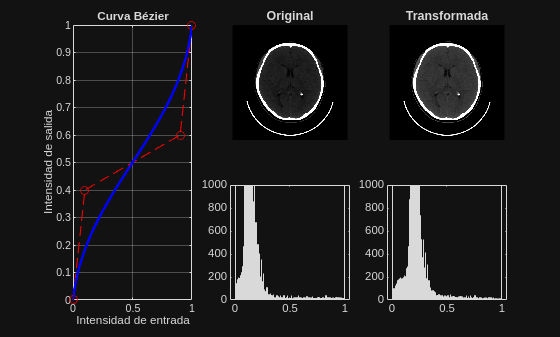

% puntos de la curva
P0 = [0 0];
P1 = [0.1 0.6];
P2 = [0.9 0.4];
P3 = [1 1];

ctrlPts = [P0; P1; P2; P3];

[B,X_bezier] = beziercurve(ctrlPts, X_norm);


subplot(131)

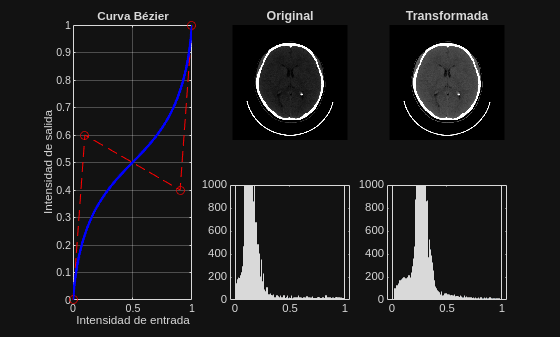

plot(ctrlPts(:,1), ctrlPts(:,2), 'ro--'); 
hold on;
plot(B(:,1), B(:,2), 'b','LineWidth',2);
hold off;
xlabel('Intensidad de entrada');
ylabel('Intensidad de salida');
title('Curva Bézier');
grid on;

subplot(232);
imshow(X_norm);
title("Original");

subplot(235);
histogram(X_norm(:), linspace(0,1, 256));
ylim([0 1000]);


subplot(233);
imshow(X_bezier);
title("Transformada");

subplot(236);
histogram(X_bezier(:), linspace(0,1, 256));
ylim([0 1000]);